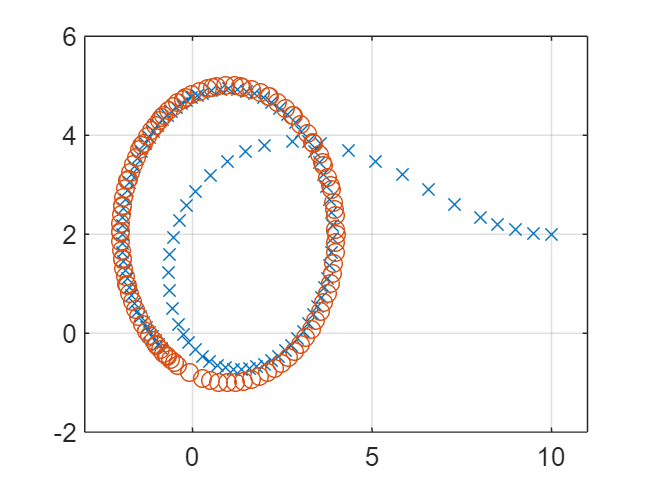

clear all
close all
hold off
[t,r]=ode45(@fang_die_Katz, [0 10*pi], [10 2]); %[Zeitdauer] und [Startposition]
plot(r(:,1), r(:,2),'x')%Roboter
xlim([-3 11])
ylim([-2 6])
k= katze(t)';

hold on
plot(k(:,1),k(:,2),'o')%Katze
grid on

Abstand = norm(k(end,:)-r(end,:))

Abstand = 0.4573

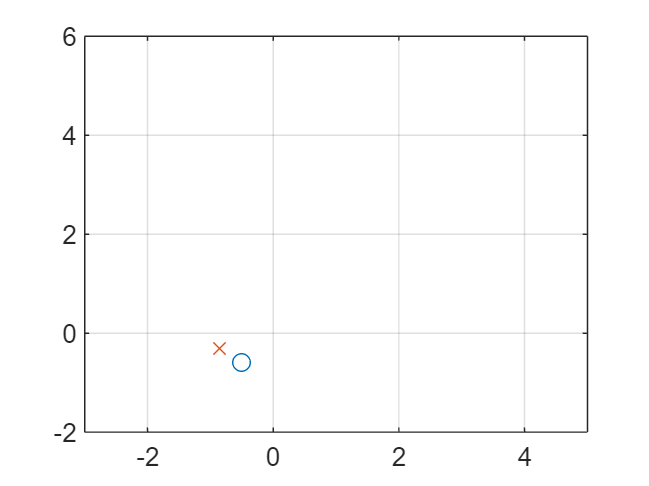

figure
%Der zweite Plot zeigt die letzten Positionen an.
plot(k(end,1),k(end,2),'o')
hold on
plot(r(end,1),r(end,2),'x')
xlim([-3 5])
ylim([-2 6])
grid on